# Tutorial 6 - Simulate Thermal Performance

## Introduction

In this tutorial, we will use a P4D model to simulate the thermal performance. We'll use the same model from Tutorial 1

## Setup material properties

jsonstruct_material = parseBattmoJson('Examples/jsondatafiles/sample_input.json');
jsonstruct_material.include_current_collectors = true;

## Setup the geometry

We use a 3D geometry where it is easier to visualize the thermal effects.

jsonstruct_geometry = parseBattmoJson('Examples/JsonDataFiles/geometry3d.json');
disp(jsonstruct_geometry)

    include_current_collectors: 1
                      Geometry: [1×1 struct]
             NegativeElectrode: [1×1 struct]
             PositiveElectrode: [1×1 struct]
                     Separator: [1×1 struct]
                  ThermalModel: [1×1 struct]


We merge the json structure. We get a warning for each field that gets different values from the given inputs. The rule is that the first input takes precedence, the warning can be switched off be setting the `'warn'` option to `false` in the call to `mergeStructs`.

jsonstruct = mergeStructs({jsonstruct_geometry , ...
    jsonstruct_material});

mergeStructs: Parameter Geometry.case is assigned twice with different values. Value from first jsonstruct is used.
mergeStructs: Parameter NegativeElectrode.Coating.thickness is assigned twice with different values 0.0001 and 6.4e-05, relative difference is 0.219512. Value from first jsonstruct is used.
mergeStructs: Parameter NegativeElectrode.Coating.numberOfDiscreteCells is assigned twice with different values 3 and 10, relative difference is 0.538462. Value from first jsonstruct is used.
mergeStructs: Parameter NegativeElectrode.CurrentCollector.numberOfDiscreteCells is assigned twice with different values 2 and 10, relative difference is 0.666667. Value from first jsonstruct is used.
mergeStructs: Parameter PositiveElectrode.Coating.thickness is assigned twice with different values 8e-05 and 5.7e-05, relative difference is 0.167883. Value from first jsonstruct is used.
mergeStructs: Parameter PositiveElectrode.Coating.numberOfDiscreteCells is assigned twice with different values 


jsonstruct.use_thermal = true;

We setup the model using the json structure.

model = setupModelFromJson(jsonstruct);

## Run the simulation

We run the simulation. We have used here a standard discharge control at C-Rate=1.

output = runBattery(jsonstruct);

Solving timestep 001/155:                      -> 1 Second, 50 Milliseconds
Solving timestep 002/155: 1 Second, 50 Milliseconds -> 2 Seconds, 100 Milliseconds
Solving timestep 003/155: 2 Seconds, 100 Milliseconds -> 4 Seconds, 200 Milliseconds
Solving timestep 004/155: 4 Seconds, 200 Milliseconds -> 8 Seconds, 400 Milliseconds
Solving timestep 005/155: 8 Seconds, 400 Milliseconds -> 16 Seconds, 800 Milliseconds
Solving timestep 006/155: 16 Seconds, 800 Milliseconds -> 33 Seconds, 600 Milliseconds
Solving timestep 007/155: 33 Seconds, 600 Milliseconds -> 67 Seconds, 200 Milliseconds
Solving timestep 008/155: 67 Seconds, 200 Milliseconds -> 100 Seconds, 800 Milliseconds
Solving timestep 009/155: 100 Seconds, 800 Milliseconds -> 134 Seconds, 400 Milliseconds
Solving timestep 010/155: 134 Seconds, 400 Milliseconds -> 168 Seconds
Solving timestep 011/155: 168 Seconds          -> 201 Seconds, 599 Milliseconds
Solving timestep 012/155: 201 Seconds, 599 Milliseconds -> 235 Seconds, 199 Millise

## Visualisation of the results

We plot the voltage versus time for the simulation.

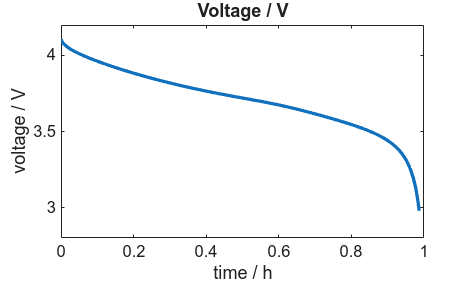

time = output.time;
E    = output.E;

set(0, 'defaulttextfontsize', 15);
set(0, 'defaultaxesfontsize', 15);
set(0, 'defaultlinelinewidth', 3);

figure
plot(time/hour, E)
title('Voltage / V');
xlabel('time / h');
ylabel('voltage / V');

We plot the minimum and maximum values of the temperature in the model as a function of time. The temperature for each grid cell, is stored in `state.ThermalModel.T`. For each computed step, we extract the minimum and maximum value of the temperature

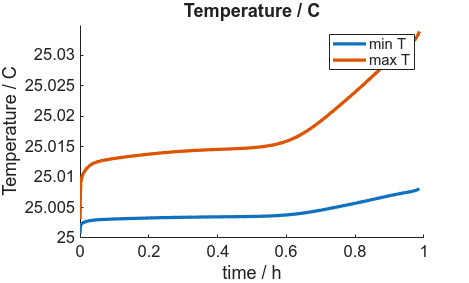

T0 = PhysicalConstants.absoluteTemperature;

states = output.states;
Tmin = cellfun(@(state) min(state.ThermalModel.T + T0), states);
Tmax = cellfun(@(state) max(state.ThermalModel.T + T0), states);

figure
hold on
plot(time / hour, Tmin, 'displayname', 'min T');
plot(time / hour, Tmax, 'displayname', 'max T');
title('Temperature / C')
xlabel('time / h');
ylabel('Temperature / C');

legend show

## Temperature distribution at final time

We have access to the temperature distribution for all the time steps. Here, we plot the temperature on the 3D model. We find a extensive set of plotting functions in [MRST](https://www.sintef.no/Projectweb/MRST/). You may be interested to have a look at the [Visualization Tutorial](https://www.sintef.no/projectweb/mrst/documentation/tutorials/visualization-tutorial/). We use [plotCellData](https://github.com/SINTEF-AppliedCompSci/MRST/blob/main/core/plotting/plotCellData.m) to plot the temperature. The function [plotToolbar.m](https://github.com/SINTEF-AppliedCompSci/MRST/blob/main/visualization/mrst-gui/plotToolbar.m) is also convenient to visualize values inside the domain in a interactive way.

state = states{end}

state = struct with fields:
    NegativeElectrode: [1×1 struct]
    PositiveElectrode: [1×1 struct]
          Electrolyte: [1×1 struct]
         ThermalModel: [1×1 struct]
              Control: [1×1 struct]
                 time: 3.551735376630604e+03

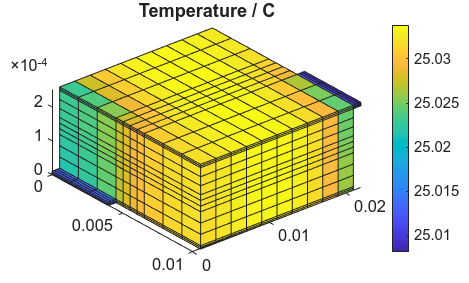

figure
plotCellData(model.ThermalModel.grid, ...
    state.ThermalModel.T + T0);
colorbar
title('Temperature / C');
view([50, 50]);

## The external heat transfer coefficient

The external heat transfer coefficient and the external temperature have a strong influence on the value of the temperature inside the model. The value of the external temperature has been given in the json input and passed to the model.

disp(model.ThermalModel.externalTemperature);

     2.981500000000000e+02


The values of the heat transfer coefficient have been processed from the json structure. For this 3D geometry, the external heat transfer coefficient is given by a value that is used at the tab

disp(jsonstruct.ThermalModel.externalHeatTransferCoefficientTab);

        1000


and an other that is used for the remaining external faces,

disp(jsonstruct.ThermalModel.externalHeatTransferCoefficient);

   100


From those values, when the model is setup, a value is assigned to all the external faces of the model. This value is stored in `model.ThermalModel.externalHeatTransferCoefficient`. Let us plot its value the 3D model. In the coupling term of the thermal model (coupling to the exterior model), we get the list of the face indices that are coupled thermally, which are in fact allthe external faces.

extfaceind = model.ThermalModel.couplingTerm.couplingfaces;
G          = model.ThermalModel.grid;
nf         = G.faces.num;

We create a vector with one value per face and we set this value equal to the external heat transfer coefficient for the corresponding external face.

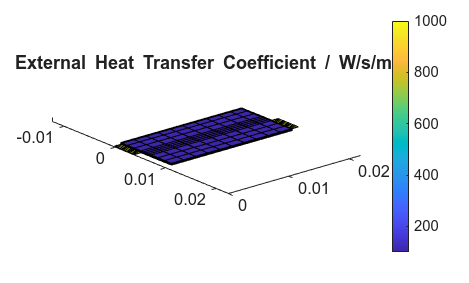

val = NaN(nf, 1);
val(extfaceind) = model.ThermalModel.externalHeatTransferCoefficient;

figure
plotFaceData(G, val, 'edgecolor', 'black');
axis equal
view([50, 20]);
title('External Heat Transfer Coefficient / W/s/m^2')
colorbar

Let us modify the heat transfer coefficients and rerun the simulation to observe the effects.

jsonstruct.ThermalModel.externalHeatTransferCoefficientTab = 100;
jsonstruct.ThermalModel.externalHeatTransferCoefficient = 0;

We run the model for the new values

output = runBattery(jsonstruct);

Solving timestep 001/155:                      -> 1 Second, 50 Milliseconds
Solving timestep 002/155: 1 Second, 50 Milliseconds -> 2 Seconds, 100 Milliseconds
Solving timestep 003/155: 2 Seconds, 100 Milliseconds -> 4 Seconds, 200 Milliseconds
Solving timestep 004/155: 4 Seconds, 200 Milliseconds -> 8 Seconds, 400 Milliseconds
Solving timestep 005/155: 8 Seconds, 400 Milliseconds -> 16 Seconds, 800 Milliseconds
Solving timestep 006/155: 16 Seconds, 800 Milliseconds -> 33 Seconds, 600 Milliseconds
Solving timestep 007/155: 33 Seconds, 600 Milliseconds -> 67 Seconds, 200 Milliseconds
Solving timestep 008/155: 67 Seconds, 200 Milliseconds -> 100 Seconds, 800 Milliseconds
Solving timestep 009/155: 100 Seconds, 800 Milliseconds -> 134 Seconds, 400 Milliseconds
Solving timestep 010/155: 134 Seconds, 400 Milliseconds -> 168 Seconds
Solving timestep 011/155: 168 Seconds          -> 201 Seconds, 599 Milliseconds
Solving timestep 012/155: 201 Seconds, 599 Milliseconds -> 235 Seconds, 199 Millise

We plot the results

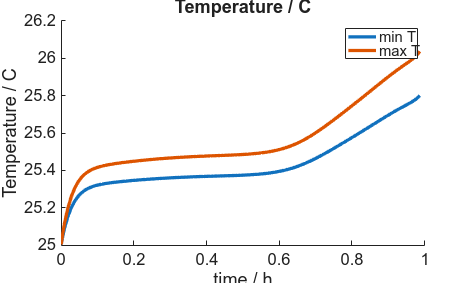

states = output.states;

Tmin = cellfun(@(state) min(state.ThermalModel.T + T0), states);
Tmax = cellfun(@(state) max(state.ThermalModel.T + T0), states);
time = output.time;

figure
hold on
plot(time / hour, Tmin, 'displayname', 'min T');
plot(time / hour, Tmax, 'displayname', 'max T');
title('Temperature / C')
xlabel('time / h');
ylabel('Temperature / C');

legend show


%{
Copyright 2021-2026 SINTEF Industry, Sustainable Energy Technology
and SINTEF Digital, Mathematics & Cybernetics.

This file is part of The Battery Modeling Toolbox BattMo

BattMo is free software: you can redistribute it and/or modify
it under the terms of the GNU General Public License as published by
the Free Software Foundation, either version 3 of the License, or
(at your option) any later version.

BattMo is distributed in the hope that it will be useful,
but WITHOUT ANY WARRANTY; without even the implied warranty of
MERCHANTABILITY or FITNESS FOR A PARTICULAR PURPOSE.  See the
GNU General Public License for more details.

You should have received a copy of the GNU General Public License
along with BattMo.  If not, see <http://www.gnu.org/licenses/>.
%}